%Observer design
A = [-1 1 0;1 -1 0;1 0 -2];
B = [0;1;0];
C = [1 0 0];
L = [-1;-1;-1]

L =     -1
    -1
    -1


eig(A+(L*C))    %Eigen values

ans =     -2
    -1
    -2


%Controller design
A = [-1 1 0;1 -1 0;1 0 -2];
B = [0;1;0];
C = [1 0 0];
poles = [-1 -1 -1]

poles =     -1    -1    -1


%Finding gain matrix using Ackerman pole placement
K = Ackermann(A,B,poles)   

K =      2    -1    -1


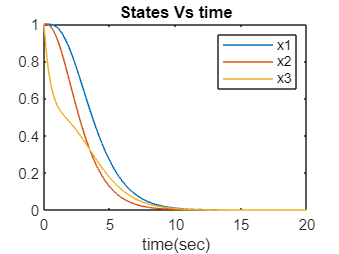

%Simulating the results

tstart = 0;
tend = 20;
dt = 0.01;
n = 1000;

tspan = transpose(linspace(tstart,tend,n));
xinit = [1 1 1 1 1 1]; %initial values of states and errors

[t,x] = ode45(@integratingfunc_SpringMass_system, tspan, xinit);
plot(t,x(:,1),t,x(:,2),t,x(:,3));
title("States Vs time")
legend(["x1","x2","x3"])
xlabel("time(sec)")

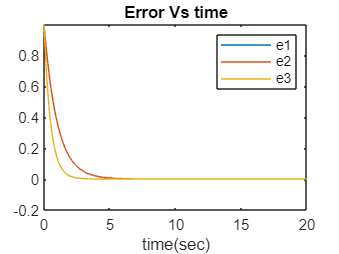

plot(t,x(:,4),t,x(:,5),t,x(:,6));
title("Error Vs time")
legend(["e1","e2","e3"])
xlabel("time(sec)")

function dxdt = integratingfunc_SpringMass_system(t,x)
%INTEGRATINGFUNC_SPRINGMASS_SYSTEM Summary of this function goes here
%   Detailed explanation goes here
A = [-1 1 0;1 -1 0;1 0 -2];
B = [0;1;0];
C = [1 0 0];
K = [2 -1 -1];
L = [-1;-1;-1];

dxdt = zeros(6,1);
%T = Tss - (k1*(pos-del)) - (k2*(v));
dxdt(1:3) = ((A-(B*K))*x(1:3)) + (B*K*x(4:6));
dxdt(4:6) = (A+(L*C))*x(4:6);
end


%Ackermann function for pole placement
function K = Ackermann(Ac,Bc,poles)

n = size(Ac,1);
m = size(Bc,2);
In = eye(n);
del_A = eye(n);
%Forming characteristic equation
for i=1:n
    del_A = del_A*(Ac-(poles(i)*In));
end
const = zeros(1,n);
const(1,n) = 1;

%Forming controllability matrix
iter = Ac*Bc;
    con = [Bc iter];
    for i = 1:n-2
        iter = Ac*iter;
        con = [con iter];
    end
K = const*(con\del_A);      % For SISO K = [0 0 ...1]*inv(con)*A_desired

end
